# Geospatial Data Files and Displays

## 1. Map Colors and Scattered Data

What if your data is in the form of Latitude, Longitude, Value? What if you want to show an interpolated map at each latitude by longitude point, colored based on the data's value, instead of making a scatter plot?

The "`UCrustdepth.mat`" file has been created from the ECM1 model, found here: [https://www.earthcrustmodel1.com/.](https://www.earthcrustmodel1.com) Mooney, W. D., Barrera-Lopez, C.,  Suárez, M. G., & Castelblanco, M. A. (2023). Earth crustal model 1  (ECM1): A 1 x 1 global seismic and density model. *Earth-Science Reviews*, *243*, 104493.

Load `UCrustdepth.mat`, then, using [`geoloc2grid`](https://www.mathworks.com/help/map/ref/geoloc2grid.html) and [`geoshow`](https://www.mathworks.com/help/map/ref/geoshow.html?searchHighlight=geoshow&s_tid=srchtitle_support_results_1_geoshow), plot the depth data on an axesm of your choice. Geoloc2grid converts geolocated scattered data to a regular grid, `Z`, and corresponding raster reference object, `R`. We will explore `geoshow` more in section 3.

load("UCrustdepth.mat"); % adapted from https://www.earthcrustmodel1.com/
lat = UC.lat;
lon = UC.lon;

[Z,R] = geoloc2grid(UC.lat,UC.lon,UC.depth,1);

figure
axesm('apianus')
geoshow(Z,R,"DisplayType","surface")

Related functions: [`meshgrid`](https://www.mathworks.com/help/matlab/ref/meshgrid.html), [`griddata`](https://www.mathworks.com/help/matlab/ref/griddata.html?searchHighlight=griddata&s_tid=srchtitle_support_results_1_griddata), [`scatteredInterpolant`](https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html)

## 2. Reading Shapefiles

Shapefiles, with the file extension '.shp', are geospatial vector files for GIS software. They store geometric location and attribute information of geographic features. These features can be represented by lines, polygons, or points and are useful for collecting and storing map-related data. Two useful functions for loading .shp files are [`shaperead`](https://www.mathworks.com/help/map/ref/shaperead.html?s_tid=doc_ta) and [`readgeotable`](https://www.mathworks.com/help/map/ref/readgeotable.html?s_tid=doc_ta).

lands = shaperead("landareas.shp")
GT = readgeotable("landareas.shp")

What are some of the differences in the resulting variables when you read the same file in with two different functions?

## 3. Geoshow

Use `worldmap` to generate a map axis that is centered on and includes boundaries for the countries of Indonesia, Malaysia, and the Philippines. Then call `hold on` to indicate that you want to plot more information on the same axes.

figure
worldmap(["Indonesia" "Malaysia" "Philippines"])
hold on

#### Geoshow

[`Geoshow`](https://www.mathworks.com/help/map/ref/geoshow.html?searchHighlight=geoshow&s_tid=srchtitle_support_results_1_geoshow) is a versatile function for displaying locations, textures, or surfaces on different map projections. Use geoshow to display a shapefile with the variable name `GT.`

- `call GT = readgeotable("landareas.shp")`

- set the `FaceColor `of the shape to any shade of green

- use setm to customize the appearance of your labels, grids, and axes

geoshow(GT,"FaceColor",[0.5 0.7 0.5]) 
setm(gca, 'meridianlabel', 'on','MLabelParallel','south')

Add other features to your map, such as rivers and cities. 

- use the function(s) you learned above to read in data from the built-in MATLAB file `"worldrivers.shp", `and store it in the variable` rivers`

- plot the rivers on the same axes as above using `geoshow`

`Then, read in "worldcities.shp" and plot city markers on the same map axes.`

 rivers = readgeotable("worldrivers.shp");
 geoshow(rivers,"LineStyle",":","Color","blue")

 cities = readgeotable("worldcities.shp");
 geoshow(cities,"Marker","o","MarkerEdgeColor","black","MarkerFaceColor","black","MarkerSize",5.5)

Visit the [`geoshow` documentation](https://www.mathworks.com/help/map/ref/geoshow.html?searchHighlight=geoshow&s_tid=srchtitle_support_results_1_geoshow) for more examples of its functionality!

#### High Resolution Coastlines

What if you need higher resolution coastlines than what is in MATLAB by default? Sources such as the National Oceanic and Atmospheric Administration (NOAA) in the USA and the General Bathymetric Chart of the Oceans ([GEBCO](https://www.gebco.net/)) have [high resolution shoreline](https://www.ngdc.noaa.gov/mgg/shorelines/) and bathymetry data. In fact, MATLAB has special functions dedicated to easily handling this "GSHHG" data. Check out the detail using [`gshhs`](https://www.mathworks.com/help/map/ref/gshhs.html?s_tid=doc_ta) to display 200 meter resolution data! Below is an example of loading GSHHG files. The coastline files loaded below and included with this workshop are the lower-resolution version for time-saving purposes, but you can also unzip and load very high resolution coastlines with the below code:

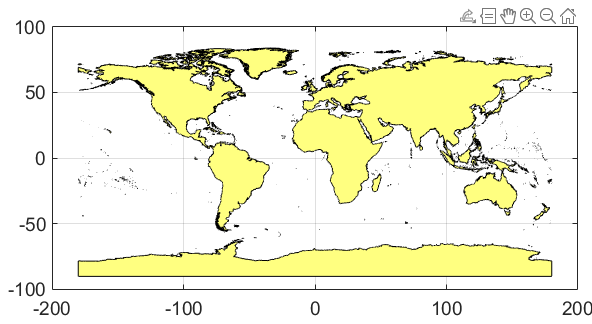

For this workshop, use `gshhs` to read in *gshhs_c.b* shoreline data and store it in the variable S. The "c" in the file name indicates "crude" resolution, so the coastlines will not be higher resolution than what is built in. However, this is simply for time-saving purposes, and outside the workshop, we invite you to read in the intermediate, high, or full resolution coastlines in all their glory.

S = gshhs('gshhs_c.b'); % Table of geometries
% c - crude; i - intermediate; h - high; f - full

figure
axesm('robinson','MapLatLimit',[-15 20],'MapLonLimit',[90 140])
geoshow(S)
gridm on

**Putting it all together **

Putting all of these options together and adding extra flair, plot the tsunami data on your map axes. Use your preferred coast line resolution and colors to visualize tsunami intensities in your area of interest. Feel free to add colorbars, transparancy, and any other helpful features. Speaking of helpful, don't forget to give your map a title!

figure
worldmap(["Indonesia" "Malaysia" "Philippines"])

Lwidth = 2.9;

Adding all of our customizations

hold on
geoshow(GT,"FaceColor",[0.5 0.7 0.5],"FaceAlpha",0.5) 
cities = readgeotable("worldcities.shp");

geoshow(cities,"Marker","x","MarkerEdgeColor","red","MarkerSize",5.5)
scatterm(tsunamis.Latitude,tsunamis.Longitude,tsunamis.MaxHeight.*10,tsunamis.Cause,'filled')

setm(gca, 'meridianlabel', 'on','MLabelParallel','south')
setm(gca,'fontsize',14)
title('Tsunami Intensity in Southeast Asia')

cb = colorbar('Ticks',[1 2 3 4]);
ylabel(cb,'Cause Category')
colormap(lines(4))
clim([0.5 4.5])